# Analysis of connectivity-related genes

clc, clear, close

projectPath = '/Users/yongbin/Documents/project_gamba/';
cd(fullfile(projectPath, 'paper', 'scripts'));
addpath(genpath('.'));

figurePath = '../figures';

% load supragranular genes
T = readtable('../data/genesets/gene_supragranular.txt', ...
    'Delimiter', '\t', 'ReadVariableNames', false);
gene_set_hse = unique(T.Var1);

% load brain genes
data = load('../data/genesets/GTEx_brain_genes_0.05_updated.mat');
gene_set_brain = data.gene_brain;

% load gene expression
ge = load('../data/gene_expression.mat');
regionDescription = ge.regionDescriptionCtx;

% load cov
IMG = load('../data/IMG_DATA_ALL_20200803.mat');
cov = IMG.stacov;

% overlap
disp(['# HSE genes: ', num2str(numel(gene_set_hse))]);

# HSE genes: 19


disp(['# BRAIN genes: ', num2str(numel(gene_set_brain))]);

# BRAIN genes: 2979


geneset = intersect(gene_set_hse, ge.gene_symbols);
[~, idx_gs] = ismember(geneset, ge.gene_symbols);
ngenes = numel(idx_gs);
tbl_hse = table(geneset);
writetable(tbl_hse, '../data/HSE.txt', 'WriteVariableNames', false);

% show gene expression profiles
geProfile = nanmean(ge.mDataGEall(:, idx_gs), 2);

% plot brain figure
cm = cbrewer('seq','Blues',100);
regions = ge.regionDescriptionAll;
plotSurfaceBoth(regions, geProfile, cm, ...
    'atlas', 'DK114_aseg', 'savePath', [figurePath, '/HSE_expression']);

## Correlation with connectome metrics

% expression profile (cortex)
GG = nanmean(ge.mDataGEctx(1:57, idx_gs), 2);
x = GG./ nanstd(GG);

% get connectome items
II = IMG.DATA_IMG_IDX == 5;
imgDATA = IMG.staIMG(:, II);

% linear regression
beta = nan(size(imgDATA,2), 1);
pval = nan(size(imgDATA,2), 1);
for ii = 1:size(imgDATA,2)
    y = imgDATA(:, ii);
    reg = regstats(y, x, 'linear', 'tstat');
    beta(ii,1) = reg.tstat.beta(2);
    pval(ii,1) = reg.tstat.pval(2);
end

% FDR
pval_adj = mafdr(pval, 'BHFDR', true);

disp('## Correlation with connectome metrics:')

## Correlation with connectome metrics:


table(IMG.DATA_IMG_DESCRIPTIONS(II), beta, pval, pval_adj)

ans = 5×4 table
          Var1           beta         pval        pval_adj 
    ________________    _______    __________    __________

    {'Strength_NOS'}    0.67765    7.0568e-09    3.5284e-08
    {'Strength_FA' }    0.26341      0.047733      0.059666
    {'Strength_SD' }    0.63747     9.693e-08    2.4233e-07
    {'Degree_SC'   }    0.19269       0.15099       0.15099
    {'Strength_FC' }    0.44961     0.0004504    0.00075066


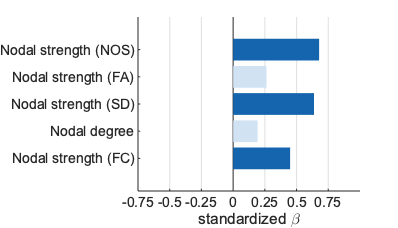

% bar plot 
sig_index = find(pval_adj < 0.05);
y_label = {'Nodal strength (NOS)'; 'Nodal strength (FA)'; 'Nodal strength (SD)';...
    'Nodal degree';'Nodal strength (FC)'};
y_barplot(beta, sig_index, ...
    'standardized \beta', y_label, ...
    fullfile(figurePath, 'HSE_connectome_chart.svg'), 1, 7, 4)

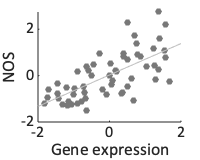

% scatter plot
y = imgDATA(:,1);
y_scatter(x, y, 'Gene expression', 'NOS', ...
    '../figures/gs1_nos.svg')

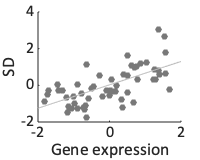


y = imgDATA(:,3);
y_scatter(x, y, 'Gene expression', 'SD', ...
    '../figures/gs1_svd.svg')

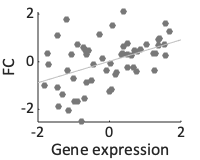


y = imgDATA(:,5);
y_scatter(x, y, 'Gene expression', 'FC', ...
    '../figures/gs1_fc.svg')

### Null models

% null-spin model
spinPath = '~/Documents/gamba/webgamba/static/data/genes_v3/';

II = IMG.DATA_IMG_IDX == 5;
for ii = 1: numel(geneset)
    jsonfile = fullfile(spinPath, [geneset{ii},'.json']);
    fid = fopen(jsonfile); 
    raw = fread(fid, inf); 
    str = char(raw'); 
    fclose(fid); 
    val = jsondecode(str);
    mtmp(ii, :) = val.spin_mbeta(II); 
    stmp(ii, :) = val.spin_sbeta(II);   
end
mbeta = nanmean(mtmp, 1)';
stdbeta = nanmean(stmp, 1)';

zval = (beta - mbeta) ./ stdbeta;
pval = 2* (1 - normcdf(abs(zval)));
disp(table(IMG.DATA_IMG_DESCRIPTIONS(II), zval, pval))

          Var1           zval        pval   
    ________________    ______    __________

    {'Strength_NOS'}    3.3989    0.00067669
    {'Strength_FA' }    1.6158       0.10613
    {'Strength_SD' }    2.4983      0.012479
    {'Degree_SC'   }    1.2464       0.21261
    {'Strength_FC' }    2.0843      0.037131



sig_index = find(pval < 0.05 & pval_adj < 0.05);

% bar plot null-spin
W = 6,H = 4;

W = 6

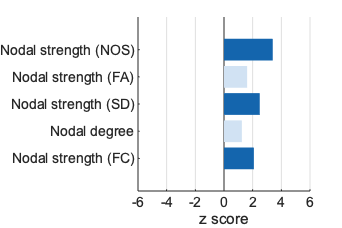

y_barplot(zval, sig_index, ...
    'z score', y_label, ...
    fullfile(figurePath, 'HSE_connectome_chart_nspin.svg'), ...
    1, W, H);

% null-random
nrandomPath = '~/Documents/gamba/webgamba/static/data/null_random/';
jsonfile = fullfile(nrandomPath, ['gs_', num2str(numel(idx_gs)),'.json']);

fid = fopen(jsonfile); 
raw = fread(fid, inf); 
str = char(raw'); 
fclose(fid); 
val = jsondecode(str);

II = IMG.DATA_IMG_IDX == 5;
mbeta = val.mbeta(II);
stdbeta = val.stdbeta(II);

zval = (beta - mbeta) ./ stdbeta;
pval = 2 * (1 - normcdf(abs(zval)));
disp(table(IMG.DATA_IMG_DESCRIPTIONS(II), zval, pval))

          Var1           zval        pval   
    ________________    ______    __________

    {'Strength_NOS'}    5.8924    3.8066e-09
    {'Strength_FA' }    2.6527     0.0079853
    {'Strength_SD' }    4.7576    1.9593e-06
    {'Degree_SC'   }    1.7847      0.074308
    {'Strength_FC' }    3.2001      0.001374



sig_index = find(pval < 0.05 & pval_adj < 0.05);

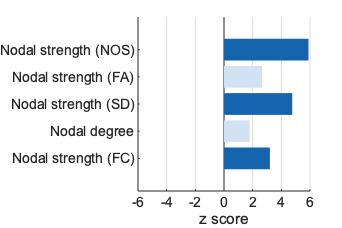

y_barplot(zval, sig_index, ...
    'z score', y_label, ...
    fullfile(figurePath, 'HSE_connectome_chart_nrandom.svg'), ...
    1, W, H);

% null-brain
nbrainPath = '~/Documents/gamba/webgamba/static/data/null_random_brain/';
jsonfile = fullfile(nbrainPath, ['brain_gs_', num2str(numel(idx_gs)),'.json']);

fid = fopen(jsonfile); 
raw = fread(fid, inf); 
str = char(raw'); 
fclose(fid); 
val = jsondecode(str);
mbeta = val.mbeta(II);
stdbeta = val.stdbeta(II);

zval = (beta - mbeta) ./ stdbeta;
pval = 2* (1 - normcdf(abs(zval)));
disp(table(IMG.DATA_IMG_DESCRIPTIONS(II), zval, pval))

     zval         pval        pval_adj 
    _______    __________    __________

     4.4414    8.9358e-06    3.5284e-08
     1.9812      0.047565      0.059666
     4.3427    1.4074e-05    2.4233e-07
    0.93438       0.35011       0.15099
     2.7473     0.0060092    0.00075066



          Var1           zval         pval   
    ________________    _______    __________

    {'Strength_NOS'}     4.4414    8.9358e-06
    {'Strength_FA' }     1.9812      0.047565
    {'Strength_SD' }     4.3427    1.4074e-05
    {'Degree_SC'   }    0.93438       0.35011
    {'Strength_FC' }     2.7473     0.0060092



sig_index = find(pval < 0.05 & pval_adj < 0.05);

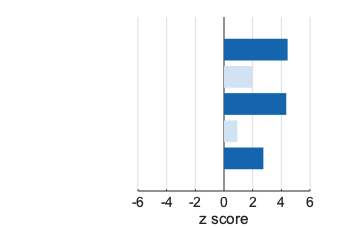

% bar plot, null-brain
y_barplot(zval, sig_index, ...
    'z score', y_label, ...
    fullfile(figurePath, 'HSE_connectome_chart_nbrain.svg'), ...
    0, W, H);

% null-coexpression
G = ge.mDataGEctx(:, idx_gs);
Rtmp = corr(G);
Rtmp = Rtmp - diag(diag(Rtmp));
Rtmp = triu(Rtmp);
orgCoexp = nanmean(nonzeros(Rtmp));

MM = numel(idx_gs);
NN = round(orgCoexp * 100);
NN = floor(NN./5).*5;

nCoexpPath = '~/Documents/gamba/webgamba/static/data/null_random_coexp/';
jsonfile = fullfile(nCoexpPath, ['coexp_gs_', num2str(NN), '_', num2str(MM), '.json']);

fid = fopen(jsonfile); 
raw = fread(fid, inf); 
str = char(raw'); 
fclose(fid); 
val = jsondecode(str);

mbeta = val.mbeta(II);
stdbeta = val.stdbeta(II);
zval = (beta - mbeta) ./ stdbeta;
pval = 2* (1 - normcdf(abs(zval)));
disp(table(IMG.DATA_IMG_DESCRIPTIONS(II), zval, pval))

          Var1           zval        pval   
    ________________    ______    __________

    {'Strength_NOS'}    5.7123    1.1144e-08
    {'Strength_FA' }    2.5034      0.012299
    {'Strength_SD' }    4.5275    5.9676e-06
    {'Degree_SC'   }    1.6821      0.092541
    {'Strength_FC' }    3.2406     0.0011927



sig_index = find(pval < 0.05 & pval_adj < 0.05);

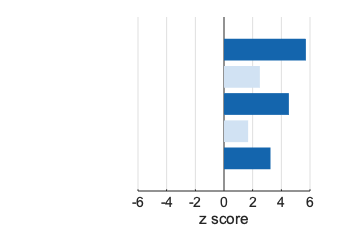

y_barplot(zval, sig_index, ...
    'z score', y_label, ...
    fullfile(figurePath, 'HSE_connectome_chart_ncoexp.svg'), ...
    0, W, H)

## (not incl. in paper) HSE genes showed higher expression within which regions?

jsonfile = fullfile('../../results/random_gene',...
    ['ge_gs_', num2str(ngenes),'.json']);
fid = fopen(jsonfile); 
raw = fread(fid, inf); 
str = char(raw'); 
fclose(fid); 
val = jsondecode(str);

zval = (G1 - val.mGE) ./ val.stdGE;
pval = 2 * (1 - normcdf(abs(zval)));
pval_adj = mafdr(pval, 'BHFDR', true);

% significant regions (FDR q < 0.05)
table(G1(pval_adj < 0.01), zval(pval_adj < 0.01), ...
    pval_adj(pval_adj < 0.01), ge.regionDescriptionAll(pval_adj<0.01))

ans = 16×4 table
      Var1       Var2         Var3                       Var4                 
    ________    _______    __________    _____________________________________

    -0.44882    -4.0493    0.00046963    {'ctx-lh-caudalanteriorcingulate_1' }
     0.21695     5.3949    2.1934e-06    {'ctx-lh-caudalmiddlefrontal_1'     }
    -0.24202    -3.3363     0.0049403    {'ctx-lh-entorhinal_1'              }
     0.24198     3.1609     0.0067111    {'ctx-lh-inferiorparietal_1'        }
      0.4335      3.085     0.0081431    {'ctx-lh-inferiorparietal_2'        }
     0.41971      5.777    4.8655e-07    {'ctx-lh-paracentral_1'             }
     0.51318     3.2268     0.0057234    {'ctx-lh-precentral_3'              }
     0.12111     3.2625     0.0054375    {'ctx-lh-precentral_4'              }
     -0.5627     -4.122    0.00046963    {'ctx-lh-rostra

T = table(ge.regionDescriptionAll, zval, pval_adj);
T.Properties.VariableNames = {'Regions', 'z_score', 'Adjusted_p'};
writetable(T, '../tables1.csv');


% ttest2 between sig regions and non-sig regions
idxSig = zval > 0 & pval_adj < 0.05;
[h, p, ~, stat] = ttest2(G1(idxSig), G1(~idxSig))

h = 1

p = 5.8165e-08

stat = struct with fields:
    tstat: 6.1662
       df: 62
       sd: 0.2342


%% Region-specificity using spin-model?
spinpath = '/Volumes/tidis/project_gamba/data/tmp/';

expression_spin = zeros(1000, 57);
for ii = 1:numel(geneset)       
    tmp = dlmread([spinpath, 'GE_spin_', geneset{ii}, '.txt']);
    expression_spin = expression_spin + tmp;
end
expression_spin = expression_spin ./ ii;

expression_spin_mean = nanmean(expression_spin, 1);
expression_spin_std = nanstd(expression_spin, '', 1);

G1ctx = nanmean(ge.mDataGEctx(:, idx_gs), 2);
zval = (G1ctx - expression_spin_mean') ./ expression_spin_std';
pval = 2 * (1 - normcdf(abs(zval)));

table(G1ctx(pval < 0.1), zval(pval < 0.1), ...
    pval(pval < 0.1), ge.regionDescriptionCtx(pval<0.1))


% SBP-spatial

pheno = dlmread('SurrogatePheno.txt');

GG = nanmean(ge.mDataGEctx(1:57, idx_gs), 2);
x = GG./ nanstd(GG);

for ii = 1:size(pheno, 1)
    y = pheno(ii, :)' ./ std(pheno(ii, :)');
    reg = regstats(y, x, 'linear', 'tstat');
    beta_sbp(ii,1) = reg.tstat.beta(2);
    pval_sbp(ii,1) = reg.tstat.pval(2);
end

zscore_sbp = (beta - mean(beta_sbp)) ./ std(beta_sbp) 

